Consider a target shape and load that is unreachable with a regular muscle design:

N_segs = 5;
Q = [0; -10; 0];

overall_g_circ_right_goal = [0.5; 0; 1];
seg_g_circ_right_goal = overall_g_circ_right_goal / N_segs;
arm_g_circ_right_goal = repmat(overall_g_circ_right_goal, [1, N_segs]);

l_0 = overall_g_circ_right_goal(1);
rho_constant = 0.05;
test_straight_arm = ArmSeriesFactory.constant_2d_muscle_arm(N_segs, rho_constant, l_0);
rxn_needed = test_straight_arm.calc_external_reaction(Q, arm_g_circ_right_goal);
internal_needed = -rxn_needed;

We will first show that this target point and load is not reachable with the muscles that we have designed

% Define load scenario
p = [60; 0; 60; 0];
Q = [0; -10; 0];
Q_frame = "World";
N_segments = 4;
l_0 = 0.5;

%% Create a no-taper arm
rho_outer_base = 0.06;
rho_inner_base = 0.01;
constant_arm = ArmSeriesFactory.constant_2d_antagonist_arm(N_segments, rho_inner_base, rho_outer_base, l_0);
constant_arm.set_mechanics(BasicPolyBellowMechanics(l_0), [1, 4]);
constant_arm.set_mechanics(AnnealedGinaMuscleMechanics(l_0), [2, 3]);
constant_arm.solve_equilibrium_gina(p, Q);

fzero residual is nonzero (> 0.01). Printing: 
   -0.0021   -0.0045   -0.0112   -0.0232
    0.0000    0.0001    0.0001   -0.0004
    0.2006    0.4133    1.0380    1.8354



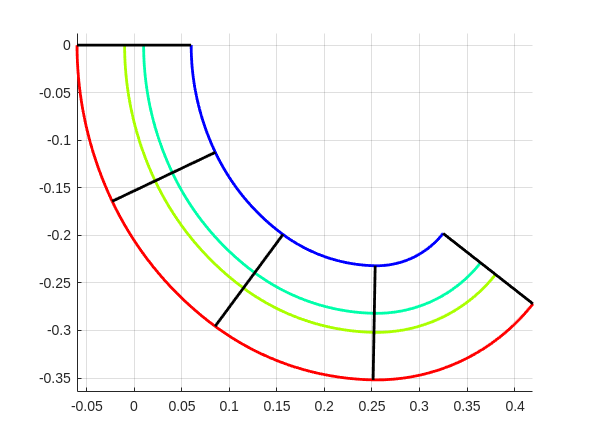

Plotter2D.plot_arm_series(constant_arm, axes(figure()));

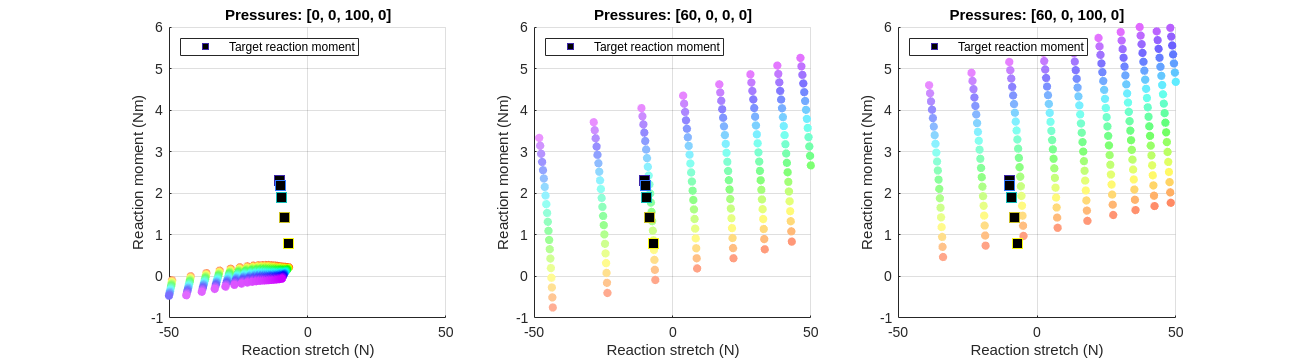

% Analyze the force function that results from combining the force
% functions of each side's muscle pair
rho_inner = 0.02;
N_rhos = 20;
N_ls = 40;
rho_outers = linspace(0.02, 0.08, N_rhos);
l_0s = linspace(0.45, 0.55, N_ls);

p_antagonist = [0; 0; 0; 0];

ps = [
    0, 0, 100, 0;
    60, 0, 0, 0;
    60, 0, 100, 0
]';
n_pressure = size(ps, 2);

figure("Position", [0, 0, 1800, 500])
for i_pressure = 1 : n_pressure
    p_i = ps(:, i_pressure);

    cell_rl = cell(N_rhos, N_ls);
    cell_arm_segments = cell(N_rhos, N_ls);
    cell_rxns = cell(N_rhos, N_ls);
    cell_colors = cell(N_rhos, N_ls);
    for i = 1 : N_rhos
        rho_i = rho_outers(i);
        for j = 1 : N_ls
            l_0_j = l_0s(j);
            % Calculate the internal reaction moment that the muscles would create
            % at that curvature.
            segment_ij = ArmSegmentFactory.make_2d_antagonism(rho_inner, rho_i, l_0_j, false);
            segment_ij.set_mechanics(GinaMuscleMechanics(l_0_j), [2, 3]);
            segment_ij.set_mechanics(BasicBellowMechanics(l_0_j), [1, 4]);
        
            cell_arm_segments{i, j} = segment_ij;
            cell_rl{i, j} = [rho_i; l_0_j];
            rxns_i = segment_ij.calc_internal_reaction(p_i, overall_g_circ_right_goal);
            cell_rxns{i, j} = rxns_i;
            cell_colors{i, j} = [i/N_rhos * 0.8; j/N_ls * 0.75 + 0.25; 1];
        end
    end
    
    mat_rl = [cell_rl{:}];
    mat_rxns = [cell_rxns{:}];
    mat_hsv = [cell_colors{:}];
    mat_rgb = hsv2rgb(mat_hsv');
    
    subplot(1, n_pressure, i_pressure);
    hold on
    scatter(mat_rxns(1, :), mat_rxns(3, :), [], mat_rgb, "filled");
    scatter(internal_needed(1, :), internal_needed(3, :), 100, linspace(0, 1, N_segs), 'square', "markerfacecolor", 'k')
    
    grid on
    xlabel("Reaction stretch (N)")
    ylabel("Reaction moment (Nm)")
    legend(["", "Target reaction moment"], "location", "northwest")
    xlim([-50, 50])
    ylim([-1, 6])
    title(sprintf("Pressures: [%d, %d, %d, %d]", p_i(1), p_i(2), p_i(3), p_i(4)))
end

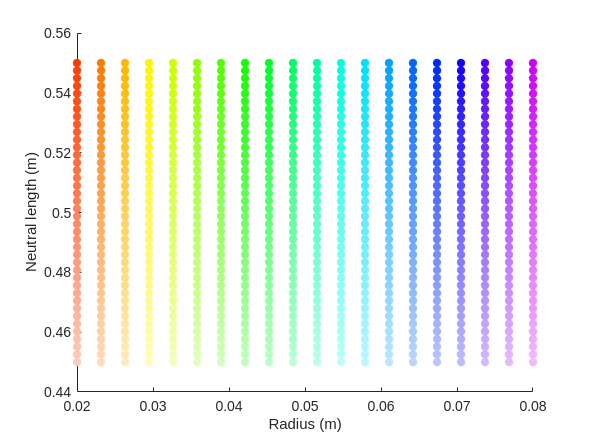

figure()
scatter(mat_rl(1, :), mat_rl(2, :), [], mat_rgb, "filled");
xlabel("Radius (m)");
ylabel("Neutral length (m)")

    Comparing an antagonist and traditional arm's ability to reach a single target point and load does not sufficiently demonstrate the key strength of antagonism. We can see from above that the combination of bellows with muscles enables arm segments to exert larger reaction moments. However, the same can be achieved by designing stronger individual muscles. The largest advantage of antagonism is that it enables a further degree of control to the force curve on each side, thus enabling a more diverse loaded workspace. A key question for our paper is therefore to effectively communicate this categorical advantage of antagonism.

    So far, we have come up with two main approaches to do so. The first is to directly show the increase in loaded workspace size, which we can do through the funnel plots. The funnel plot's strength is that it directly captures how increasing load shrinks an arm design's workspace. However, to effectively illustrate this point through the creation of the funnel surface, the workspace for eac load must be reduced to a single line, even though it is in fact an area and contains other information such as orientation. Finally, while the funnel plot is good at demonstrating the difference between two chosen arm designs, such a choice is descriptive rather than prescriptive: it does not tell us anything about what we can do to further improve the arm designs.

    Here, we propose an alternative to the funnel plot. To move from merely describing an arm's capabilities to prescribing design requirements, we need to incorporate more specifitiy. By specifying a specific task trajectory and load, we can nail down a number of key-points along the trajectory. Having a set of key-points enables us to kinematically select a set of arm geometries (segment curvatures and lengths) that will reach each of these keypoints. Once the arm kinematics are established, we can compute the reaction forces and moments that each segment needs to generate to maintain static equilibrium. These requirements will inform the selection of a muscle force function that 

THOUGHT:

- The "if the rainbow overshoots the reaction requirements at max inflation then there exists a pressure where it overlaps - and hence arms with this muscle are capable of reaching these loads at these pressures" is merely a manifestation of the intermediate-value theorem: if at p=0 the rainbow is below the required forces, and at p=p_max it is above, and assuming everything is smooth, thus rainbow must pass through the required forces for some p. We don't need to know what the value is, but the intermediate value theorem guarantees existence.

- This means that instead of solving p1, p2, ..., pn for equality, we can merely solve for p's where f > or < certain values.

- After this, the specifics of whether we fix the muscle parameters and solve for the specific designs (which we previously did with the rainbow plot) or if we fix the arm desgin and solve for muscle parameters can be taken in either direction

Here, we introduce a visual framework for identifying whether an arm composed of a set of actuators will be capable of producing the expected actuator force curves. We will first extract three keypoints along a trajectory where a robot arm is opening a drawer:

%% Step 1: Define target trajectory keybpoints
% Base pose: hanging down
pose_base = [0; 0; -pi/2];

% Keypoint poses: [x y theta]
pose_1 = [0.3; -0.4; 0];
pose_2 = [0.2; -0.4; 0];
pose_3 = [0.1; -0.4; 0];

poses = [pose_1 pose_2 pose_3];

% Create load vector
qx = 2; % Load of opening the drawer: 1N
Q = [qx; 0; 0]; % If we move to the left to open the drawer, then the drawer force will pull to the right

% Step 2: For each pose, find a shearless base-curve which reaches the goal point and minimizes certain desired metrics:
N_segs = 3;
twist_0 = repmat([1, 0], 1, N_segs);

cell_g_circ = cell(1, size(poses, 2));
for i = 1 : size(poses, 2)
    opts = optimoptions("fsolve", "algorithm", "levenberg-marquardt");
    %soln = fsolve(@(v_in) base_curve_constraint(v_in, Pose2.hat(pose_base), Pose2.hat(poses(:, i))), twist_0, opts);
    f_constraint = @(v_in) deal(0, base_curve_constraint(v_in, Pose2.hat(pose_base), Pose2.hat(poses(:, i))));
    [soln, res] = fmincon(@base_curve_cost, twist_0, [], [], [], [], [], [], f_constraint);
    cell_g_circ{i} = v_geom_to_g_circ(soln);
end


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

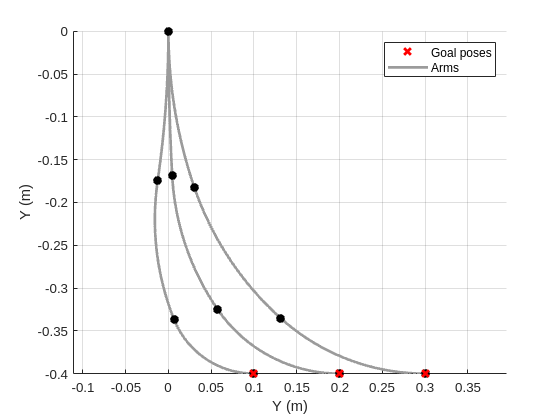


ax = axes(figure());
hold on
plot(poses(1, :), poses(2, :), 'rx', "MarkerSize", 7, "Linewidth", 2)
notch_points = zeros(3, size(poses, 2) * N_segs);

i_count = 1;
for i_pose = 1 : size(poses, 2)
    pose_i = Pose2.hat(pose_base);
    mat_g_circ_out_i = cell_g_circ{i_pose};

    notch_points_i = zeros(3, N_segs + 1);
    for i = 1 : N_segs
        rod_i = RodSegment(Pose2, 1, pose_i);
        rod_i.g_circ_right = mat_g_circ_out_i(:, i);
        Plotter2D.plot_rod(rod_i, ax);
    
        pose_i = pose_i * Twist2.expm(mat_g_circ_out_i(:, i));
        notch_points_i(:, i+1) = Pose2.vee(pose_i);
    end
    plot(notch_points_i(1, :), notch_points_i(2, :), 'ok', "markerfacecolor", "k");
end
plot(poses(1, :), poses(2, :), 'rx', "MarkerSize", 7, "Linewidth", 2)

legend(["Goal poses", "Arms"])

grid on
xlabel("Y (m)")
ylabel("Y (m)")

% Step 3: For each segment in each arm, generat a moment-image
% Compute the moments that are induced at each segment for each target pose
test_rho = 0.05;    % Arbitrary design parameter - has no influence on the external reaction moment
test_l_0 = 1;       % Arbitrary design parameter - has no influence on the external reaction moment
test_arm = ArmSeriesFactory.constant_2d_muscle_arm(N_segs, test_rho, test_l_0);

cell_g_ucirc = {};
for i_target = 1 : size(poses)
    g_circ_right_i = cell_g_circ{i_target};
    cell_g_ucirc{i_target} = test_arm.calc_external_reaction(Q, g_circ_right_i);
end

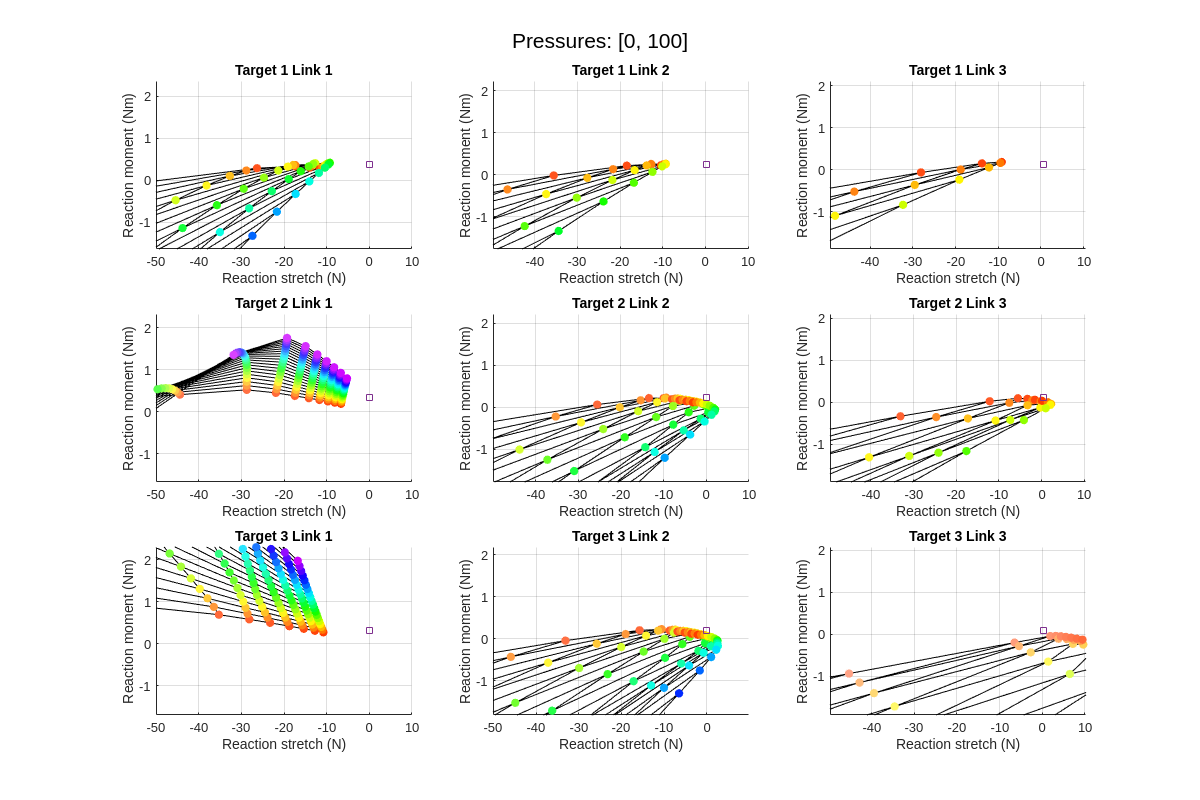

% We will first create a grid of moment-images for a two-muscle arm at its
% max inflation
p_2muscle = [0; 100];

rhos = linspace(0.02, 0.1, 20);
l_0s = linspace(0.11, 0.20, 20);

fig = figure("Position", [0, 0, 1200, 800]);

sgtitle(sprintf("Pressures: [%d, %d]", p_2muscle(1), p_2muscle(2)));
i_plot = 1;
for i_target = 1 : size(poses, 2)
    for i_seg = 1 : N_segs
        % Moment image for this segmetn
        ax = subplot(size(poses, 2), N_segs, i_plot, "parent", fig);

        g_circ_right_i = cell_g_circ{i_target}(:, i_seg);
        g_ucirc_right_i = cell_g_ucirc{i_target}(:, i_seg);
        
        f_reaction = @(rho, l_0) f_reactions_2muscle(rho, l_0, g_circ_right_i, p_2muscle);
        [mat_rxns, mat_rl, mat_rgb] = f_moment_image(f_reaction, rhos, l_0s, ax);
        plot(ax, g_ucirc_right_i(1), g_ucirc_right_i(3), 'square');
        xlim(g_ucirc_right_i(1) + [-50, 10]);
        ylim(g_ucirc_right_i(3) + [-2, 2]);
        title(sprintf("Target %d Link %d", i_target, i_seg))

        i_plot = i_plot+ 1;
    end 
end

% assert(1==0, "Stopping here - comment out this line to render a gif (est 30min run time)")
%% Plot the moment-image for a wide range of pressures
fig = figure("Position", [0, 0, 1200, 800], "color", "w");
anim = Animator(fig, 160);

n_each = 40;
n_frames = 4 * n_each;
p_max_muscle = 100;
p1 = [linspace(0, p_max_muscle, n_each), p_max_muscle * ones(1, n_each), linspace(p_max_muscle, 0, n_each), zeros(1, n_each)];
p2 = [zeros(1, n_each), linspace(0, p_max_muscle, n_each), p_max_muscle * ones(1, n_each), linspace(p_max_muscle, 0, n_each)];

ps = [p1; p2];

cell_rxns = cell(1, length(p1));
cell_rl = cell(1, length(p1));
cell_rgb = cell(1, length(p1));

N_poses = size(poses, 2);

tic
for i_p = 1 : n_frames
    p_i = ps(:, i_p);

    cell_rxns_i = cell(N_poses, N_segs);
    cell_rl_i = cell(N_poses, N_segs);
    cell_rgb_i = cell(N_poses, N_segs);

    i_plot = 1;
    clf(fig, "reset")
    sgtitle(sprintf("Pressures: [%.1f, %.1f]", p_i(1), p_i(2)));
    for i_target = 1 : N_poses
        for i_seg = 1 : N_segs
            % Moment image for this segmetn
            ax = subplot(N_poses, N_segs, i_plot, "parent", fig);

            g_circ_right_i = cell_g_circ{i_target}(:, i_seg);
            g_ucirc_right_i = cell_g_ucirc{i_target}(:, i_seg);
            
            f_reaction = @(rho, l_0) f_reactions_2muscle(rho, l_0, g_circ_right_i, p_i);
            [mat_rxns, mat_rl, mat_rgb] = f_moment_image(f_reaction, rhos, l_0s, ax);
            plot(ax, g_ucirc_right_i(1), g_ucirc_right_i(3), 'square');
            xlim(g_ucirc_right_i(1) + [-50, 10]);
            ylim(g_ucirc_right_i(3) + [-2, 2]);
            title(sprintf("Target %d Link %d", i_target, i_seg))

            cell_rxns_i{i_target, i_seg} = mat_rxns;
            cell_rl_i{i_target, i_seg} = mat_rl;
            cell_rgb_i{i_target, i_seg} = mat_rgb;

            i_plot = i_plot+ 1;
        end 
    end

    cell_rxns{i_p} = cell_rxns_i;
    cell_rl{i_p} = cell_rl_i;
    cell_rgb{i_p} = cell_rgb_i;

    fprintf("Rendering frame %d\n", i_p);
    anim.get_frame();
end

Rendering frame 1


Rendering frame 2
Rendering frame 3
Rendering frame 4
Rendering frame 5
Rendering frame 6
Rendering frame 7
Rendering frame 8
Rendering frame 9
Rendering frame 10
Rendering frame 11
Rendering frame 12
Rendering frame 13
Rendering frame 14
Rendering frame 15
Rendering frame 16
Rendering frame 17
Rendering frame 18
Rendering frame 19
Rendering frame 20
Rendering frame 21
Rendering frame 22
Rendering frame 23
Rendering frame 24
Rendering frame 25
Rendering frame 26
Rendering frame 27
Rendering frame 28
Rendering frame 29
Rendering frame 30
Rendering frame 31
Rendering frame 32
Rendering frame 33
Rendering frame 34
Rendering frame 35
Rendering frame 36
Rendering frame 37
Rendering frame 38
Rendering frame 39
Rendering frame 40
Rendering frame 41
Rendering frame 42
Rendering frame 43
Rendering frame 44
Rendering frame 45
Rendering frame 46
Rendering frame 47
Rendering frame 48
Rendering frame 49
Rendering frame 50
Rendering frame 51
Rendering frame 52
Rendering frame 53
Rendering frame 54
R

save("2_muscle_moment_image_p_contour", "cell_rxns", "cell_rl", "cell_rgb")
anim.save_gif("Pressure-square-moment-image");
toc

Elapsed time is 881.951993 seconds.


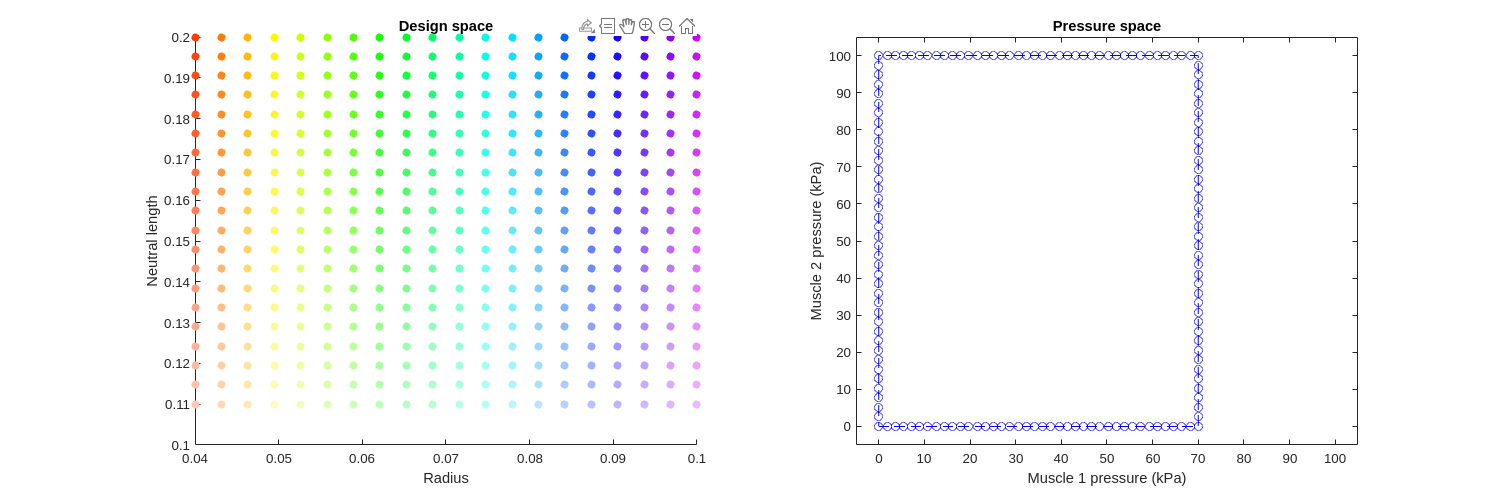

figure("Position", [0, 0, 1500, 500])
subplot(1, 2, 1);
hold on
scatter(mat_rl(1, :), mat_rl(2, :), [], mat_rgb, "filled");
xlabel("Radius")
ylabel("Neutral length")
title("Design space")

subplot(1, 2, 2)
plot(ps(1, :), ps(2, :), 'bo--')
xlim([-5, 105])
ylim([-5, 105])
xlabel("Muscle 1 pressure (kPa)")
ylabel("Muscle 2 pressure (kPa)")
title("Pressure space")

As we can see through the above work, there are a number of segments where their required reaction moments cannot be generated by any arm design at any pressure using our muscles.

We will now create a similar plot for an arm designed with antagonism, and we will hopefully see that the antagonistic arm will actually be able to reach these moment requirements.

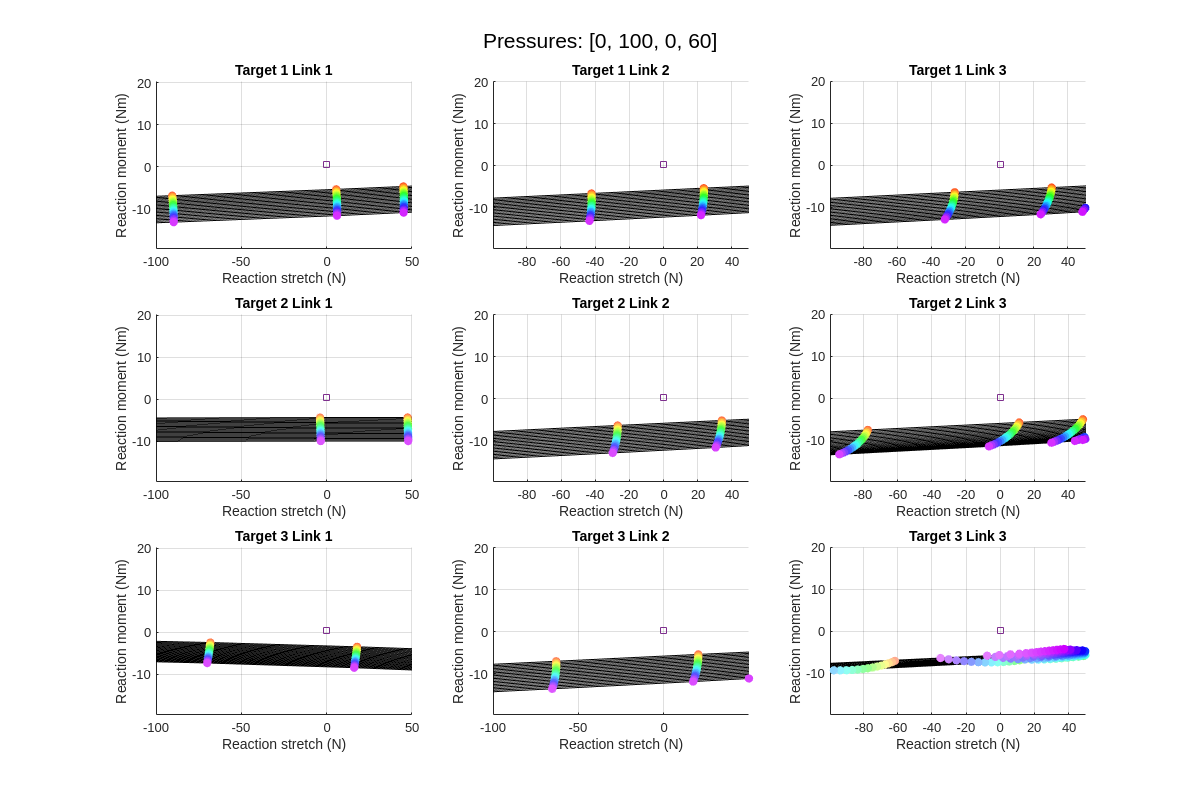

p_4muscle = [0; 100; 0; 60];

rhos = linspace(0.04, 0.1, 20);
l_0s = linspace(0.11, 0.20, 20);

fig = figure("Position", [0, 0, 1200, 800]);

sgtitle(sprintf("Pressures: [%d, %d, %d, %d]", p_4muscle(1), p_4muscle(2), p_4muscle(3), p_4muscle(4)));
i_plot = 1;
for i_target = 1 : size(poses, 2)
    for i_seg = 1 : N_segs
        % Moment image for this segmetn
        ax = subplot(size(poses, 2), N_segs, i_plot, "parent", fig);

        g_circ_right_i = cell_g_circ{i_target}(:, i_seg);
        g_ucirc_right_i = cell_g_ucirc{i_target}(:, i_seg);
        
        f_reaction = @(rho, l_0) f_reactions_4muscle(rho, l_0, g_circ_right_i, p_4muscle);
        [mat_rxns, mat_rl, mat_rgb] = f_moment_image(f_reaction, rhos, l_0s, ax);
        plot(ax, g_ucirc_right_i(1), g_ucirc_right_i(3), 'square');
        xlim(g_ucirc_right_i(1) + [-100, 50]);
        ylim(g_ucirc_right_i(3) + [-20, 20]);
        title(sprintf("Target %d Link %d", i_target, i_seg))

        i_plot = i_plot+ 1;
    end 
end

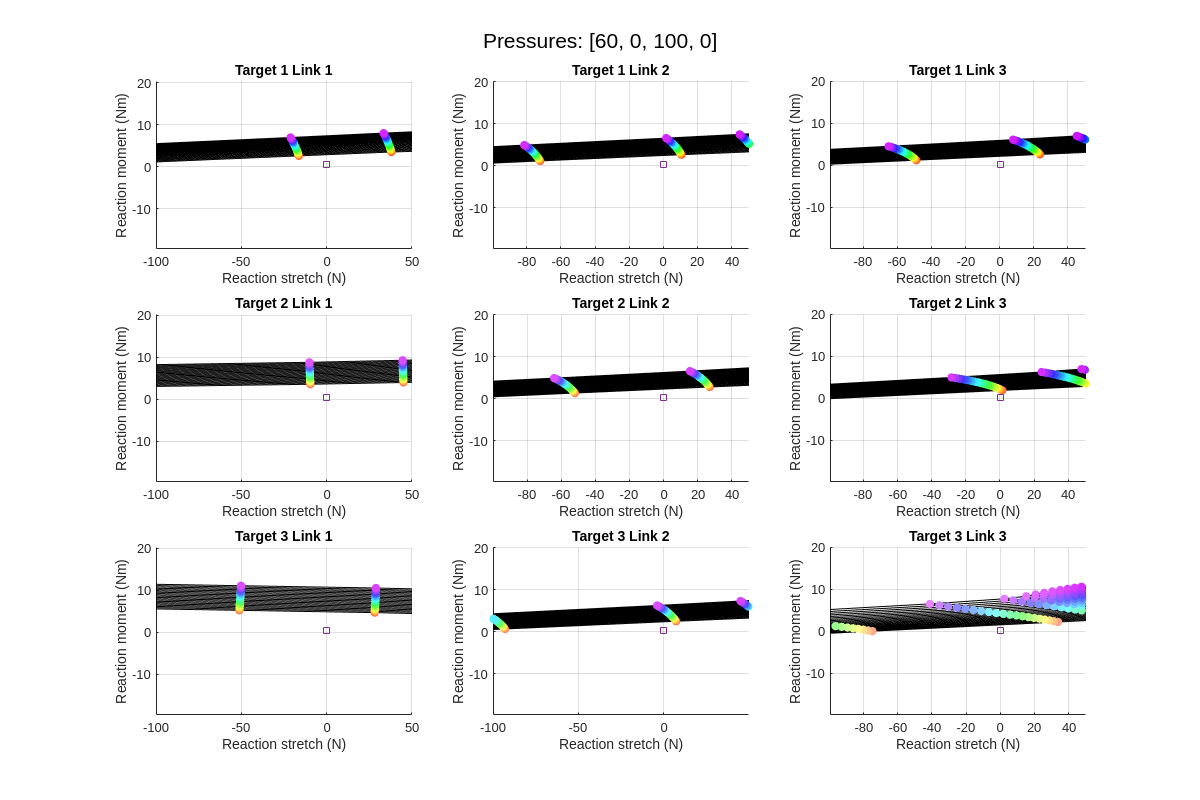

p_4muscle = [60; 0; 100; 0];

rhos = linspace(0.04, 0.1, 20);
l_0s = linspace(0.11, 0.20, 20);

fig = figure("Position", [0, 0, 1200, 800], "color", "w");

sgtitle(sprintf("Pressures: [%d, %d, %d, %d]", p_4muscle(1), p_4muscle(2), p_4muscle(3), p_4muscle(4)));
i_plot = 1;
for i_target = 1 : size(poses, 2)
    for i_seg = 1 : N_segs
        % Moment image for this segmetn
        ax = subplot(size(poses, 2), N_segs, i_plot, "parent", fig);

        g_circ_right_i = cell_g_circ{i_target}(:, i_seg);
        g_ucirc_right_i = cell_g_ucirc{i_target}(:, i_seg);
        
        f_reaction = @(rho, l_0) f_reactions_4muscle(rho, l_0, g_circ_right_i, p_4muscle);
        [mat_rxns, mat_rl, mat_rgb] = f_moment_image(f_reaction, rhos, l_0s, ax);
        plot(ax, g_ucirc_right_i(1), g_ucirc_right_i(3), 'square');
        xlim(g_ucirc_right_i(1) + [-100, 50]);
        ylim(g_ucirc_right_i(3) + [-20, 20]);
        title(sprintf("Target %d Link %d", i_target, i_seg))

        i_plot = i_plot+ 1;
    end 
end

Since we have seen that on the maximal actuations in each direction "bound" the target reaction, and since all constituitive equations are continuous, by the intermediate-value theorem we know that for some some pressure there exists a design within our design space which can reach the target moments.

To solidify this understanding, let's create a new gif sweeping the entire reaction space, but this time with antagonism.

re_render = false;
if ~re_render
    load("antagonism_moment_image_p_contour.mat")
    assert(1==0, "Stopping here - comment out this line to render a gif (est 30min run time)")    
end

Error using assert
Stopping here - comment out this line to render a gif (est 30min run time)


%% Plot the moment-image for a wide range of pressures
fig = figure("Position", [0, 0, 1200, 800]);

n_each = 40;
n_frames = 4 * n_each;
anim = Animator(fig, n_frames);

p_max_muscle = 100;
p_max_bellow = 70;

p1 = [linspace(0, p_max_bellow, n_each), p_max_bellow * ones(1, n_each), linspace(p_max_bellow, 0, n_each), zeros(1, n_each)];
p2 = [zeros(1, n_each), linspace(0, p_max_muscle, n_each), p_max_muscle * ones(1, n_each), linspace(p_max_muscle, 0, n_each)];
p3 = [linspace(0, p_max_muscle, n_each), p_max_muscle * ones(1, n_each), linspace(p_max_muscle, 0, n_each), zeros(1, n_each)];
p4 = [zeros(1, n_each), linspace(0, p_max_bellow, n_each), p_max_bellow * ones(1, n_each), linspace(p_max_bellow, 0, n_each)];

ps = [p1; p2; p3; p4];

cell_rxns = cell(1, length(p1));
cell_rl = cell(1, length(p1));
cell_rgb = cell(1, length(p1));

N_poses = size(poses, 2);

tic
for i_p = 1 : n_frames
    p_i = ps(:, i_p);

    cell_rxns_i = cell(N_poses, N_segs);
    cell_rl_i = cell(N_poses, N_segs);
    cell_rgb_i = cell(N_poses, N_segs);

    i_plot = 1;
    clf(fig, "reset")
    sgtitle(sprintf("Pressures: [%.f, %.f, %.f, %.f]", p_i(1), p_i(2), p_i(3), p_i(4)));
    for i_target = 1 : N_poses
        for i_seg = 1 : N_segs
            % Moment image for this segmetn
            ax = subplot(N_poses, N_segs, i_plot, "parent", fig);

            g_circ_right_i = cell_g_circ{i_target}(:, i_seg);
            g_ucirc_right_i = cell_g_ucirc{i_target}(:, i_seg);
            
            f_reaction = @(rho, l_0) f_reactions_4muscle(rho, l_0, g_circ_right_i, p_i);
            [mat_rxns, mat_rl, mat_rgb] = f_moment_image(f_reaction, rhos, l_0s, ax);
            plot(ax, g_ucirc_right_i(1), g_ucirc_right_i(3), 'square');
            xlim(g_ucirc_right_i(1) + [-100, 50]);
            ylim(g_ucirc_right_i(3) + [-13, 13]);
            title(sprintf("Target %d Link %d", i_target, i_seg))

            cell_rxns_i{i_target, i_seg} = mat_rxns;
            cell_rl_i{i_target, i_seg} = mat_rl;
            cell_rgb_i{i_target, i_seg} = mat_rgb;

            i_plot = i_plot+ 1;
        end 
    end

    cell_rxns{i_p} = cell_rxns_i;
    cell_rl{i_p} = cell_rl_i;
    cell_rgb{i_p} = cell_rgb_i;

    fprintf("Rendering frame %d\n", i_p);
    anim.get_frame();
end
save("antagonism_moment_image_p_contour", "cell_rxns", "cell_rl", "cell_rgb")
anim.save_gif("Pressure-square-moment-image-antagonism");
toc

For each of the cells in the moment-image, we are interested in finding the arm design particles that can encircle target reaction. Let's start by doing this for one subplot. We will first find all the arm designs that encircle the target reaction using the matlab `inpolygon()` function. Then, we will plot the pre-image of these points in the design space, ie the regions in the design space which meet our design requirements for that segment.

This code can be executed just from the .mat files that are saved from the operation of the previous code. The intention is for the previous code to be rarely run as it takes a long time, and afterwards to work with the .mat files. 

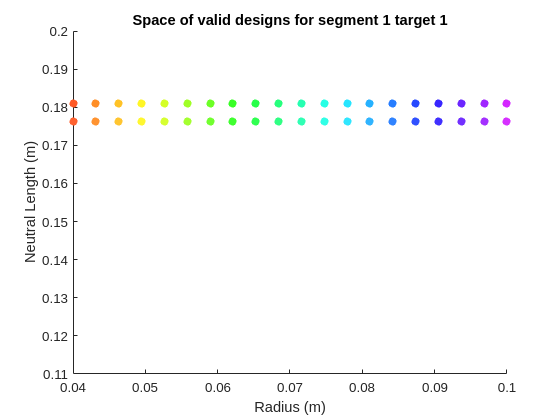

cell_rxns_3d = cat(3, cell_rxns{:});

% Matrix of the design space (should be constant across the board)
mat_rl = cell_rl{1}{1, 1};
mat_rgb = cell_rgb{1}{1, 1};

n_designs = 400; % TODO: Programmatically get this number
n_pressures = length(cell_rxns);
mat_reactions_11 = cat(3, cell_rxns_3d{1, 1, :});
ucirc_11 = cell_g_ucirc{1}(:, 1);

designs_isvalid = false(n_designs, 1);
for i = 1 : n_designs
    % Get the reaction-space polygon associated with this design
    % [
    %   qf_p1, qf_p2, qf_p3, ..., qf_pm
    %   qm_p1, qm_p2, qm_p3, ..., qm_pm
    % ]
    % where each [qf_p1, qm_p1] comes from the design's column in the
    % pressure's associated reaction matrix. 
    
    % Fetch polygon points for design i
    Pi = mat_reactions_11([1, 3], i, :);
    Pi = reshape(Pi, 2, n_pressures);

    designs_isvalid(i) = inpolygon(ucirc_11(1), ucirc_11(3), Pi(1, :), Pi(2, :));
end

figure()
scatter(mat_rl(1, designs_isvalid), mat_rl(2, designs_isvalid), [], mat_rgb(designs_isvalid, :), "filled");
xlim([0.04, 0.1]);
ylim([0.11, 0.2]);
xlabel("Radius (m)");
ylabel("Neutral Length (m)")
title("Space of valid designs for segment 1 target 1")

function v_cost = base_curve_cost(v_in)
    % Formulate cost term as the variance of the lengths
    mat_g_circ_right  = v_geom_to_g_circ(v_in);

    lengths = mat_g_circ_right(1, :);
    v_cost = std(lengths);
end

function v_residual = base_curve_constraint(v_in, base_pose, goal_pose)
    % Constraint function for determining whether a set of shearless twist
    % vectors actually reach a given goal pose. 
    %
    % To be used as an equality constraitn function in calls to `fmincon()`
    %
    % v_in: vector of lengths and curvatures [lambda_1, kappa_1, lambda_2, kappa_2, ...]
    n_twists = length(v_in) / 2;
    mat_g_circ_right = v_geom_to_g_circ(v_in);

    % Integrate all the g_circ_rights in order
    pose = base_pose;
    for i = 1 : n_twists
        pose = pose * Twist2.expm(mat_g_circ_right(:, i));
    end

    rdelta_pose = inv(pose) * goal_pose;
    v_residual = Twist2.vee(logm(rdelta_pose));
    
end

function mat_g_circ_right = v_geom_to_g_circ(v_geom)
    % Convert a "geometry vector" to a matrix of twists
    n_g_circ = length(v_geom)/2;
    mat_lambda_kappa = reshape(v_geom, [2, n_g_circ]);
    lambdas = mat_lambda_kappa(1, :);
    kappas = mat_lambda_kappa(2, :);

    mat_g_circ_right = [lambdas; zeros(1,n_g_circ); kappas];
end

function [seg, reactions] = f_reactions_2muscle(rho, l_0, g_circ_right, p)
    seg = ArmSegmentFactory.make_2d_2muscle(rho, l_0);
    seg.set_mechanics(GinaMuscleMechanics(l_0));
    reactions = seg.calc_internal_reaction(p, g_circ_right);
end

function [seg, reactions] = f_reactions_4muscle(rho_out, l_0, g_circ_right, p)
    rho_in = 0.02;
    seg = ArmSegmentFactory.make_2d_antagonism(rho_in, rho_out, l_0, false);
    seg.set_mechanics(GinaMuscleMechanics(l_0), [2, 3]);
    seg.set_mechanics(BasicPolyBellowMechanics(l_0), [1, 4]);
    reactions = seg.calc_internal_reaction(p, g_circ_right);
end